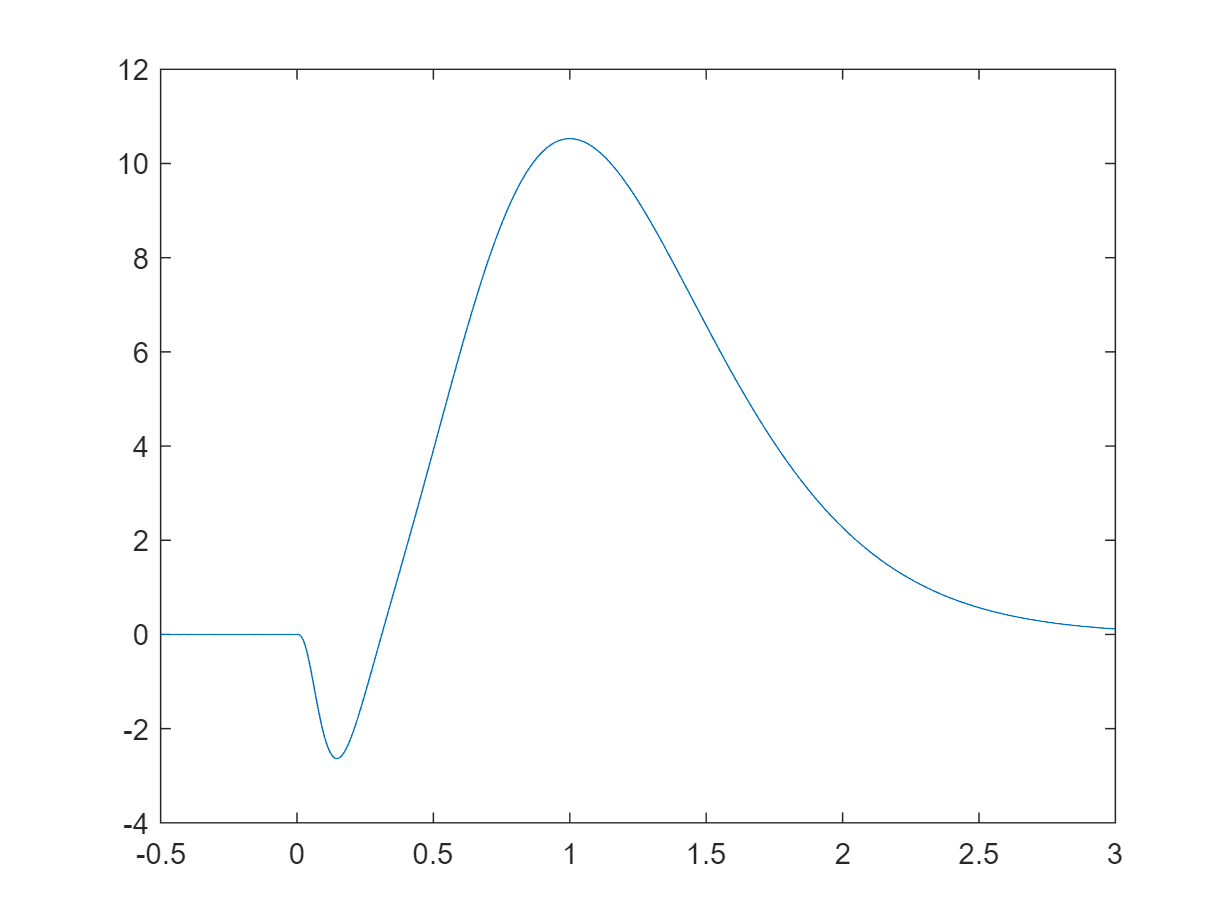

% Synthetic data script for time series analysis with PCA

% Let's construct a dataset that has known structure to test out the
% analysis procedure

% time vector: 30 Hz, with 500 ms pre-stim and 3 s post-stim
Fs = 512;
t_start = -0.5;
t_stop = 3;
time_vector = t_start:1/Fs:t_stop;

% evoked activity is a bump with negative and positive peaks 
tau_on = 0.05;
tau_off = .2;
evoke_pattern = (-2*(time_vector/tau_on).^3.*exp(-time_vector/tau_on) + ...
    0.5*(time_vector/tau_off).^5.*exp(-time_vector/tau_off)).*double(time_vector > 0);
figure()
plot(time_vector, evoke_pattern)

%%

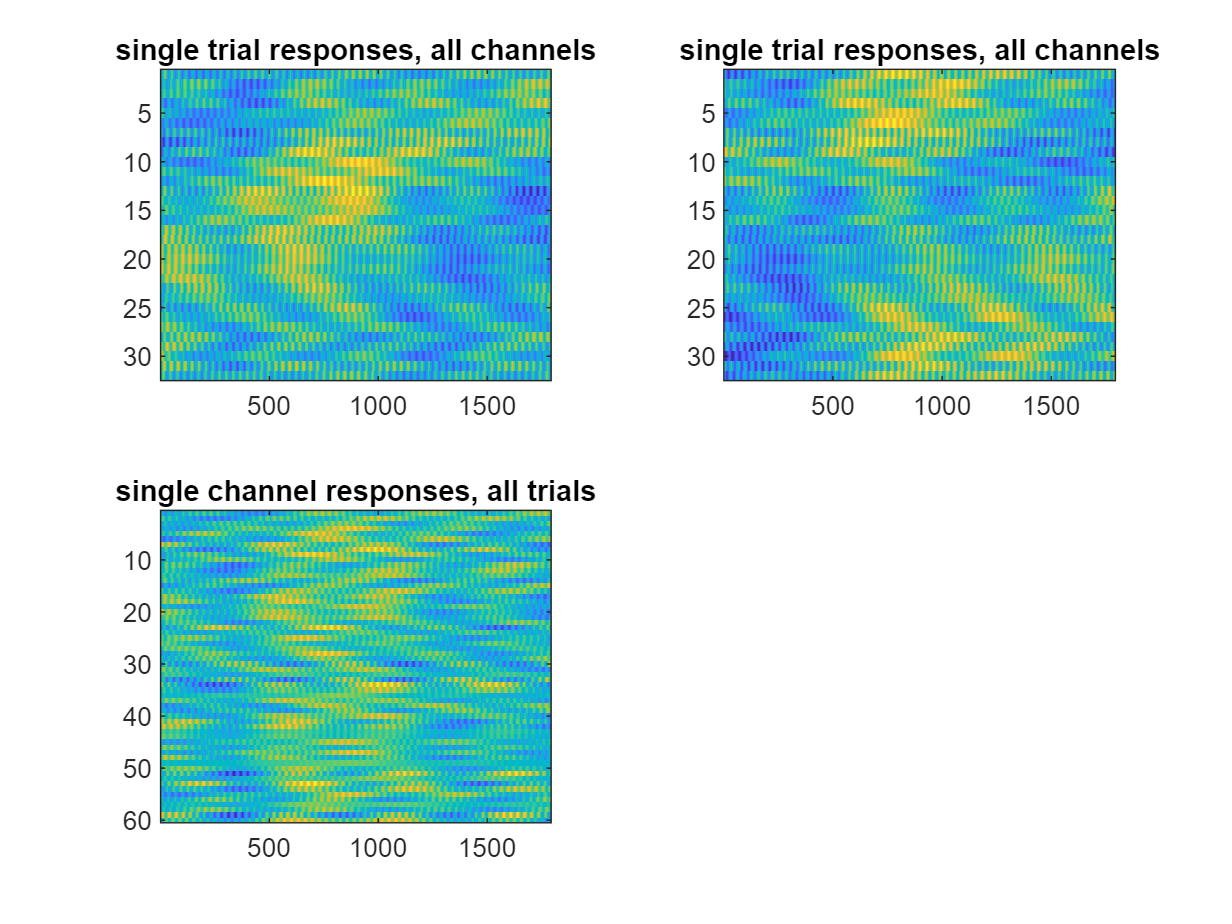

% ongoing activity is a sum of sines with different frequencies and phases
F_ongoing = 2*pi*[0.2 1 16]; 
num_freq = length(F_ongoing);

% each channel has a relative phase and a random overall amplitude 
% scale [forget about spatial patterning]
num_channels = 32;
channel_phases = 2*pi*rand(num_channels, num_freq);
channel_amplitude_scale = 0.5*(1 + rand(num_channels, num_freq, 1, 1));
% order phases in the lowest frequency
[~, ord] = sort(channel_phases(:, 1));
channel_phases = channel_phases(ord, :);

% each trial has a different amplitude of ongoing activity [add phase too]
num_trials = 60;
trial_amplitude_factor = 1 + 0.2*randn(1, 1, num_trials); % 3rd dimension will be trial
% make half the trials different
trial_amplitude_factor(:, :, end/2:end) = -1 + 2*trial_amplitude_factor(:, :, end/2:end);
trial_phase_factor = 2*pi*rand(1, num_freq, 1, num_trials);

% overall activity: trial_factor x ongoing activity + evoked activity
ft = shiftdim(bsxfun(@(freq, t_vec) freq*t_vec, F_ongoing', time_vector), -1);

base_ongoing_dynamics0 = bsxfun(@(ft, phi) (ft+phi), channel_phases, ft);

% get the trial-by-trial ongoing dynamics
base_ongoing_dynamics_trial = bsxfun(@(bod0, trial_phase) bod0+trial_phase, ...
    base_ongoing_dynamics0, trial_phase_factor);
%
base_ongoing_dynamics = squeeze(sum(bsxfun(@(amp, ft) amp.*sin(ft), ...
    channel_amplitude_scale, base_ongoing_dynamics_trial), 2));

% now generate trial-by-trial responses: linear sum of all factors 
synth_trial_data = base_ongoing_dynamics.*...
    repmat(trial_amplitude_factor, [num_channels length(time_vector) 1]) + ...
    0.1*repmat(evoke_pattern, [num_channels 1 num_trials]);


figure()
nexttile
imagesc(squeeze(synth_trial_data(:, :, 1)))
title('single trial responses, all channels')

nexttile
imagesc(squeeze(synth_trial_data(:, :, num_trials)))
title('single trial responses, all channels')

nexttile
imagesc(squeeze(synth_trial_data(4, :, :))')
title('single channel responses, all trials')

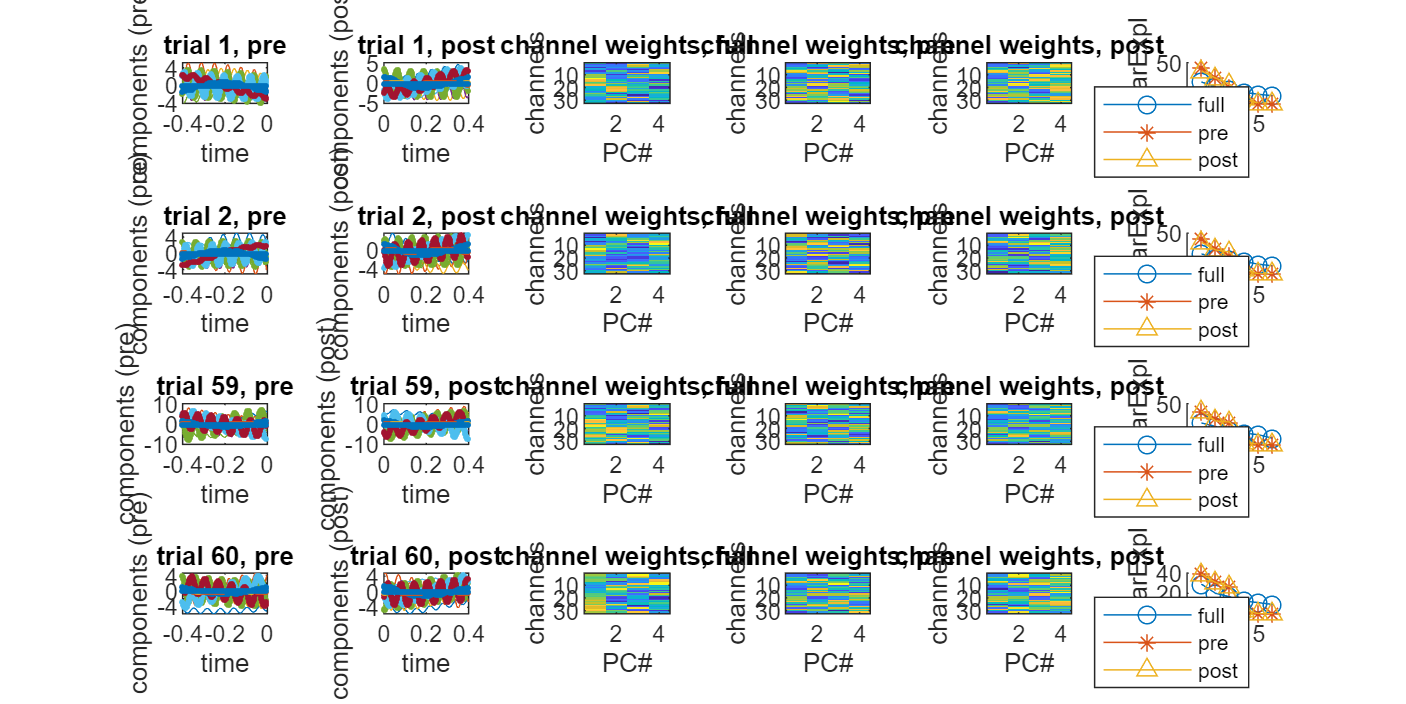

%% OK. Now, let's try our PCA analysis. 
post_window = [0 0.4];
pre_window = [-0.4 0];
pre_idx = time_vector > pre_window(1) & time_vector < pre_window(2);
post_idx = time_vector > post_window(1) & time_vector < post_window(2);

figure('Position', [100, 100, 1200, 600]); % [x, y, width, height]
tiledlayout(4, 6)

for i_trial = [1 2 num_trials-1 num_trials]

    [coeff, score, ~, ~, varExpl] = pca(synth_trial_data(:, :, i_trial)');
    
    pre_pcs = score(pre_idx, :);
    post_pcs = score(post_idx, :);
    
    % note that these are different from PCA on the pre-trial window only:
    [coeffpre, scorepre, ~, ~, varExplpre] = pca(synth_trial_data(:, pre_idx, i_trial)');
    [coeffpost, scorepost, ~, ~, varExplpost] = pca(synth_trial_data(:, post_idx, i_trial)');
    
    nexttile
    plot(time_vector(pre_idx), pre_pcs)
    hold on
    plot(time_vector(pre_idx), scorepre, '.-', 'linewidth', 1)
    title(['trial ' num2str(i_trial) ', pre'])
    ylabel('components (pre)')
    xlabel('time')
    
    
    nexttile
    plot(time_vector(post_idx), post_pcs)
    hold on
    plot(time_vector(post_idx), scorepost, '.-', 'linewidth', 1)
    title(['trial ' num2str(i_trial) ', post'])
    ylabel('components (post)')
    xlabel('time')
    
    nexttile
    imagesc(coeff(:, 1:4))
    ylabel('channels')
    xlabel('PC#')
    title('channel weights, full')
    
    nexttile
    imagesc(coeffpre(:, 1:4))
    ylabel('channels')
    xlabel('PC#')
    title('channel weights, pre')
    
    nexttile
    imagesc(coeffpost(:, 1:4))
    ylabel('channels')
    xlabel('PC#')
    title('channel weights, post')
    
    nexttile
    hold on
    plot(varExpl, 'o-')
    plot(varExplpre, '*-')
    plot(varExplpost, '^-')
    xlim([0 6])
    ylabel('PC VarExpl')
    legend({'full', 'pre', 'post'})

end